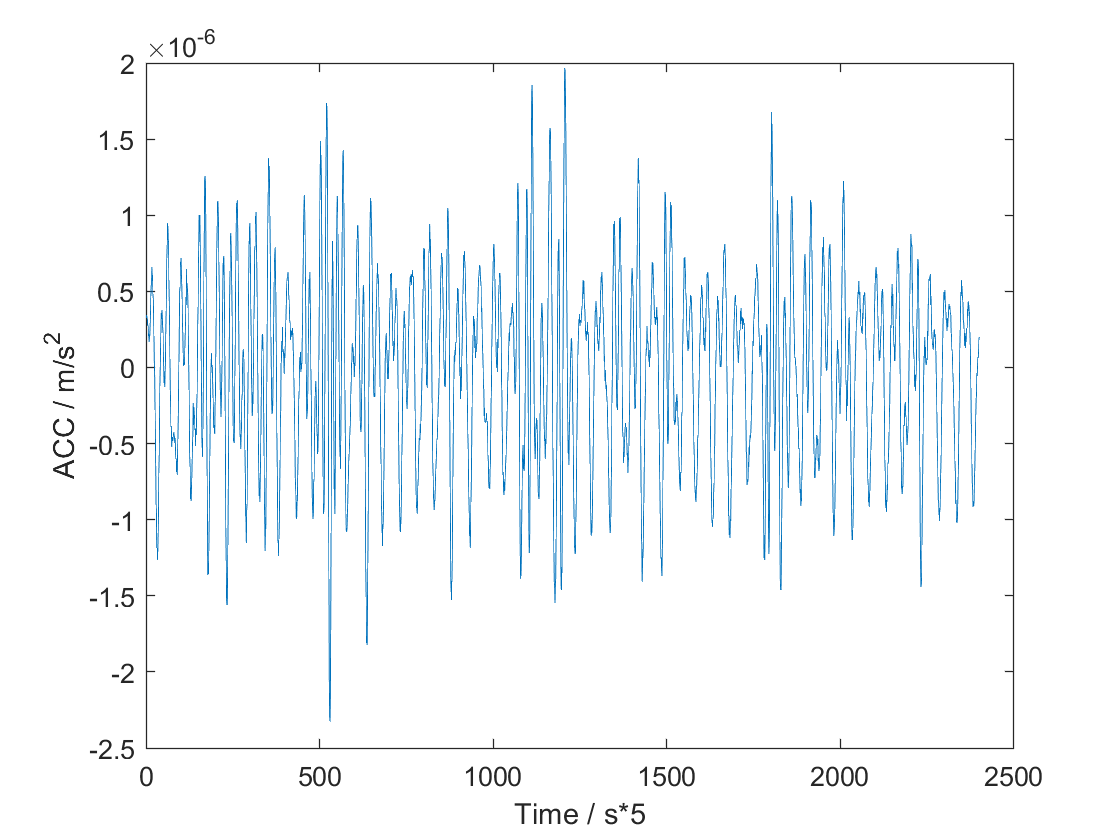

format long eng

eqa = importdata("../../temp/simu86400/eqa_86400.txt");
kbr1b_x = importdata("KBR1B_2020-09-17_Y_04.txt");
range_acc = importdata("../../temp/simu86400/simu_86400.txt");
range_acc = filter_pdfree(second_order_diff(60, 30), range_acc) / 25;
range_acc = -range_acc(1: 2400) + kbr1b_x(1: 2400, 4);
acc_grav = importdata("..//..//temp//acc_grav_calibra2.txt");
acc_grav = acc_grav(1: 86400, :);
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-17_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-17_D_04.txt");
gni_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni_b = importdata("GNI1B_2020-09-17_D_04.txt");
sca_c = importdata("SCA1B_2020-09-17_C_04.txt");
sca_d = importdata("SCA1B_2020-09-17_D_04.txt");
acc_a = importdata("ACT1B_2020-09-17_C_04.txt");
acc_b = importdata("ACT1B_2020-09-17_D_04.txt");

acc_nongrav = [acc_a.data(:, 1) - mean(acc_a.data(:, 1)), acc_a.data(:, 2) - mean(acc_a.data(:, 2)), acc_a.data(:, 3) - mean(acc_a.data(:, 3)), acc_b.data(:, 1) - mean(acc_b.data(:, 1)), acc_b.data(:, 2) - mean(acc_b.data(:, 2)), acc_b.data(:, 3) - mean(acc_b.data(:, 3))];
acc_nongrav_gcrs = zeros(size(acc_nongrav));
for i = 1: length(acc_nongrav)
    rotm_a = quat2rotm(sca_c.data(i, 2: 5));
    rotm_b = quat2rotm(sca_d.data(i, 2: 5));
    acc_nongrav_gcrs(i, 1: 3) = rotm_a * acc_nongrav(i, 1: 3)';
    acc_nongrav_gcrs(i, 4: 6) = rotm_b * acc_nongrav(i, 4: 6)';
end
acc_nongrav_rela = [acc_nongrav_gcrs(:, 1) - acc_nongrav_gcrs(:, 4), acc_nongrav_gcrs(:, 2) - acc_nongrav_gcrs(:, 5), acc_nongrav_gcrs(:, 3) - acc_nongrav_gcrs(:, 6)];
pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :)) + dot(acc_nongrav_rela(i, :), los_i(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav(1: 2400);
figure; plot(range_acc_res); xlabel("Time / s*5"); ylabel("ACC / m/s^2")

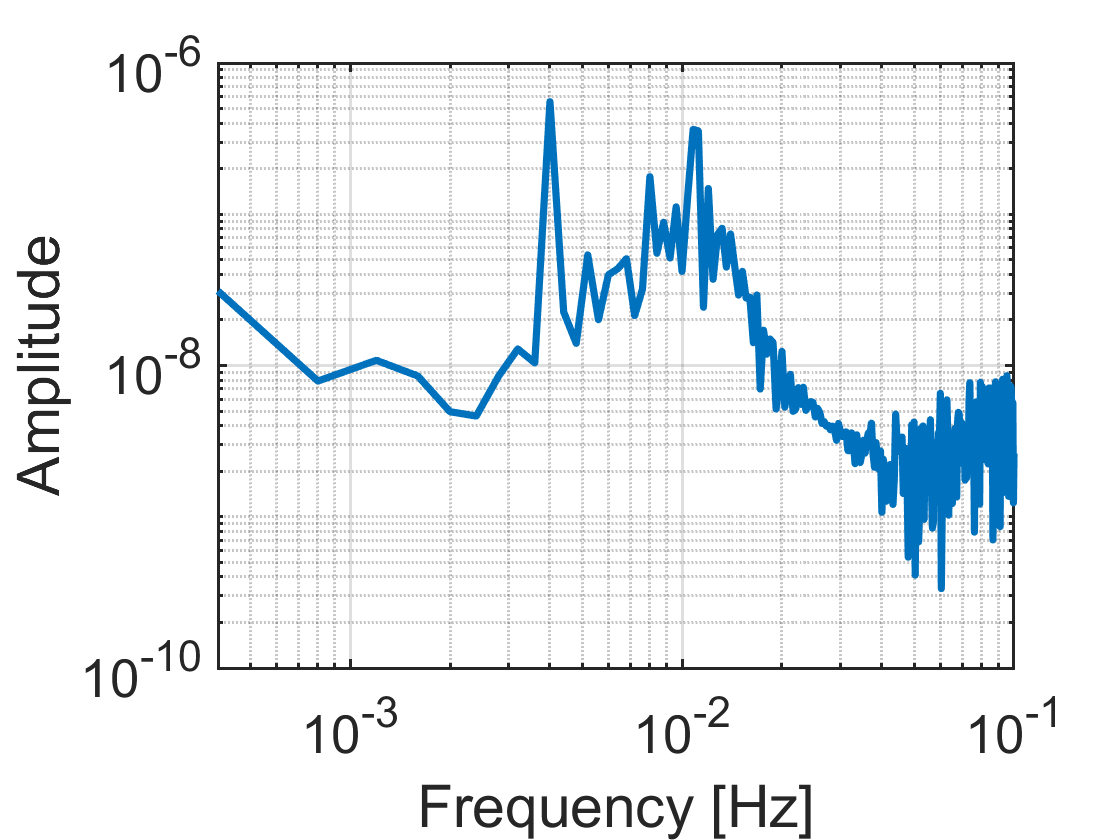

figure; fft_plot(range_acc_res(1: 500), 0.2)

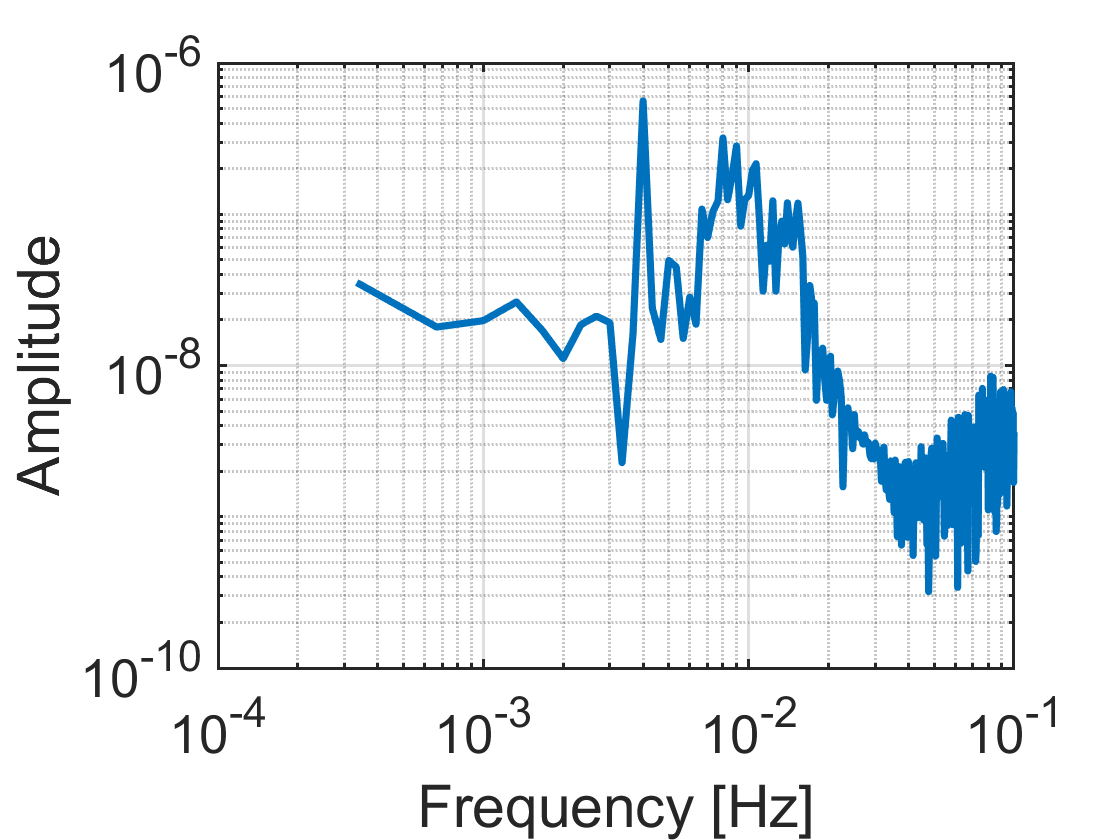

figure; fft_plot(range_acc_res(601: 1200), 0.2)

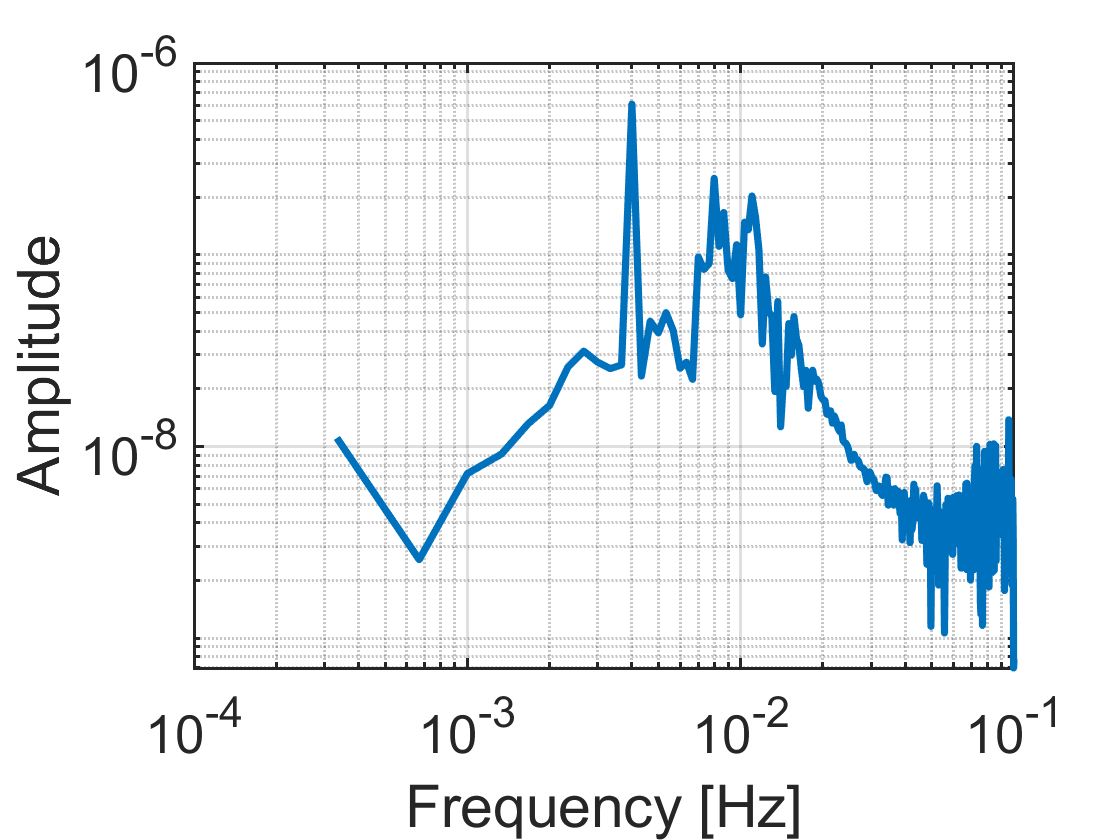

figure; fft_plot(range_acc_res(1201: 1800), 0.2)

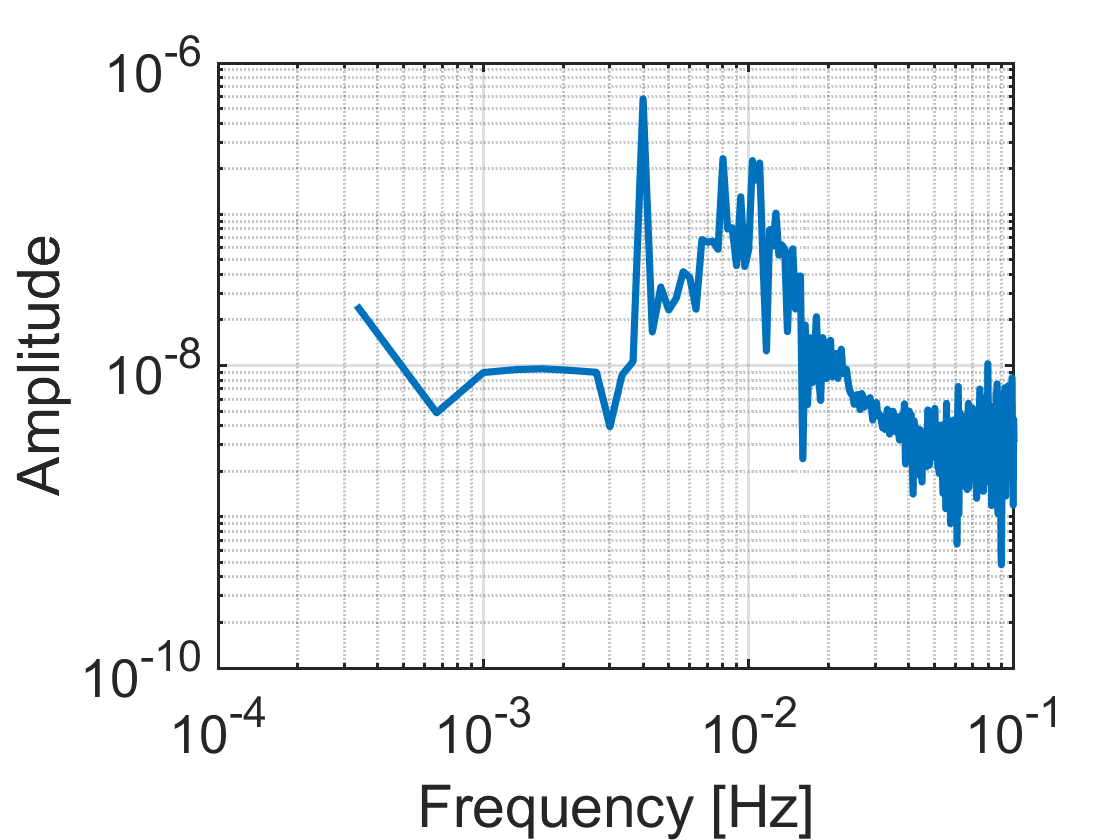

figure; fft_plot(range_acc_res(1801: 2400), 0.2)

a1 = solver_fft(filter_pdfree(Num, range_acc_res(1: 500)), 0.2)

a1 =     558.315355354450e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(1: 600, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0098。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0098。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0098。


a2 =     380.152265513891e-009
    192.304179738475e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(1: 600, 3)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0096。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0096。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0096。


a3 =     11.0182873419586e-006
    5.72294233132751e-009


q1 = (a1 - 1.5 * a2(1)) / a3(1)

q1 =    -1.08120641136498e-003


a1 = solver_fft(filter_pdfree(Num, range_acc_res(601: 1100)), 0.2)

a1 =     562.832160088921e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(601: 1200, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0087。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0087。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0087。


a2 =     381.842310882360e-009
    192.205737139923e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(601: 1200, 3)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0092。


a3 =     11.0163480315354e-006
    8.61784623555710e-009


q2 = (a1 - 1.5 * a2(1)) / a3(1)

q2 =    -901.506216596395e-006


a1 = solver_fft(filter_pdfree(Num, range_acc_res(1201: 1700)), 0.2)

a1 =     590.534086932805e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(1201: 1800, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.01。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.01。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.01。


a2 =     380.002892751390e-009
    192.431348093405e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(1201: 1800, 3)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.01。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.01。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.01。


a3 =     11.0199722334502e-006
    5.29658062494717e-009


q3 = (a1 - 1.5 * a2(1)) / a3(1)

q3 =     1.86295821539397e-003


a1 = solver_fft(filter_pdfree(Num, range_acc_res(1801: 2300)), 0.2)

a1 =     574.385248002232e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(1801: 2400, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0088。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0088。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0088。


a2 =     381.950960712723e-009
    192.341241468363e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(1801: 2400, 3)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0091。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0091。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0091。


a3 =     11.0171174264928e-006
    4.88550789447693e-009


q4 = (a1 - 1.5 * a2(1)) / a3(1)

q4 =     132.412760677262e-006


bbbb = [1.5; 3e-4; 3e-4; 1.5; 3e-4; 3e-4];
cccc = [1.5; q1; q2; 1.5; q3; q4];
q1

q1 =    -1.08120641136498e-003


q2

q2 =    -901.506216596395e-006


q3

q3 =     1.86295821539397e-003


q4

q4 =     132.412760677262e-006


acos(dot(bbbb(1: 3), cccc(1: 3)) / norm(bbbb(1: 3)) / norm(cccc(1: 3)))

ans =     1.22044559893339e-003


acos(dot(bbbb(4: 6), cccc(4: 6)) / norm(bbbb(4: 6)) / norm(cccc(4: 6)))

ans =     1.04794420148914e-003
